# International Gas Prices

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

prices = readmatrix("./data/gasprices.xlsx", Sheet="prices");
yr = readmatrix("./data/gasprices.xlsx", Sheet="yr");
country = readmatrix("./data/gasprices.xlsx", Sheet="country", OutputType='string');
litPerYear = readmatrix("./data/gasprices.xlsx", Sheet="litPerYear");

litPerGal = 3.7854;
cost = prices.*litPerYear / litPerGal;
avgCost = mean(cost);

## Task 1

The following variables are loaded from the file `gasprices.mat` or calculated in the script:

- `prices`: matrix of gasoline prices in USD/gallon where each column represents a different country and each row a different year

- `yr`: vector of year values from 1990 to 2008

- `litPerGal`: scalar number of liters in a gallon

- `litPerYear`: vector containing the average liter consumption of gasoline per individual per year from 1990 to 2008

- `country`: cell array containing the names of the countries

- `cost`: annual amount spent (in USD) over the 19 years for a person in each country

[https://www.eia.doe.gov](https://www.eia.doe.gov/)

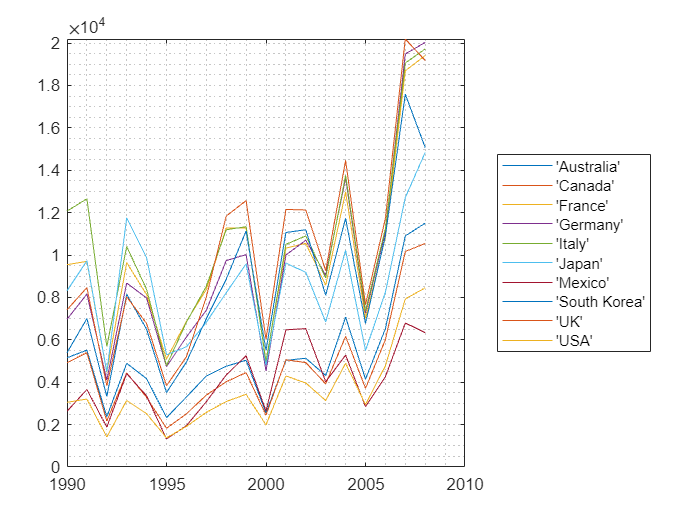

plot(yr, cost)
grid minor
legend(country, "Location", "eastoutside")

## Task 2

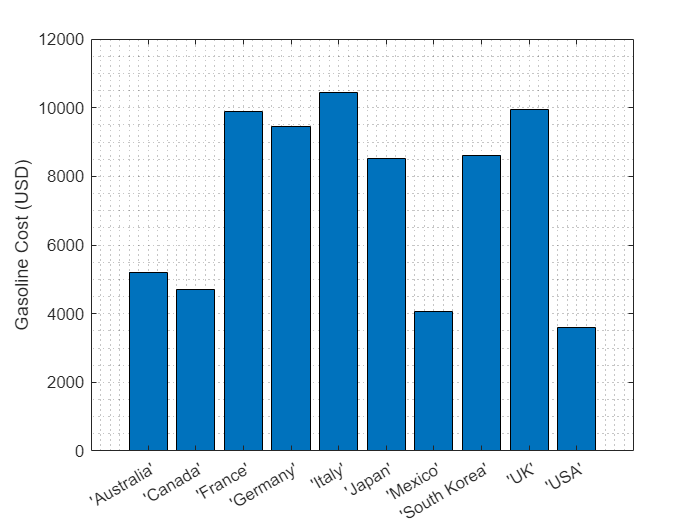

bar(avgCost)
grid minor
ylabel("Gasoline Cost (USD)")
xticklabels(country)